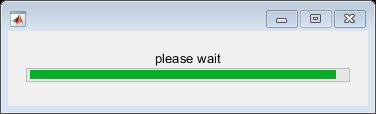

clear;
% 有BUG：只生成了31个场景，缺一个,最后一个场景的PNG通道有问题
dataset_origin_path = 'D:\Leo_files\CAVE-dataset'; %CAVE数据集
dataset_output_path = 'D:\Leo_files\CAVE-dataset-crop'; %输出文件夹
dataset_num = 32; %期望获得的数据集数量
H = 512; %原图的宽高
W = 512;
channel = 28;
H_crop = 512; %剪裁后的图片宽高(如果是512，dataset_num就是32)
W_crop = 512; 


list = dir([dataset_origin_path]);
list=list(~ismember({list.name},{'.','..'})); %从list中删除.和.. 只保留文件名

scene_num = length(list);
scene_sample_num = int8(dataset_num/scene_num);
h = waitbar(0, 'please wait');

for i = 1:scene_num
    sublist = dir([list(i).folder, '\' ,list(i).name]);
    sublist=sublist(~ismember({sublist.name},{'.','..'})); %从sublist中删除.和.. 只保留文件名
    for j = 1:size(sublist)
        imglist = dir([sublist(j).folder,'\', sublist(j).name, '\','*.png']); %这个遍历会获得根目录下所有子文件夹的图像列表
        %将imglist中的图，读入并存储到[H,W,channel]的矩阵中
        data = zeros(H,W,channel);
        for k = 1:channel
            data(:,:,k) = imread(fullfile(imglist(k).folder, imglist(k).name));
        end
        %如何做光谱插值？
        
        if H_crop == 512 && W_crop == 512
            cast = single(data(:,:,:));
            save([dataset_output_path, '\', 'scene_',num2str(i),'.mat'], "cast");
        else
            %随机生成剪裁区域
            X = randperm(W-W_crop);
            Y = randperm(H-H_crop);
            for k = 1:scene_sample_num %对光谱数据立方体进行随机剪裁，每个场景剪裁的次数根据scene_sample_num而定
                %保存剪裁结果到输出文件夹
                cast = single(data(Y(k):Y(k)+H_crop-1, X(k):X(k)+W_crop-1, :)); 
                save([dataset_output_path, '\', 'scene_',num2str(i),'_',num2str(k),'.mat'], "cast");
            end
        end
        
    end
    waitbar(i/scene_num, h);
end

无法执行赋值，因为左侧的大小为 512×512，右侧的大小为 512×512×3。

delete(h);
